%dove sono i frame
imageFolder = imageDatastore("frameTest2\");
%le immagini si portano in bianco e nero per velocizzare la computazione

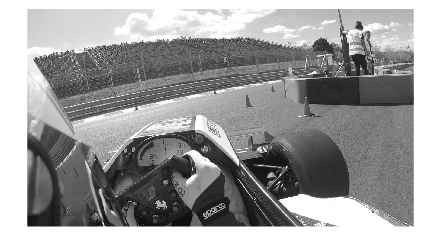

%carico prima immagine
I = 1; % first frame idx
Im1 = readimage(imageFolder, I); 
Im1 = im2gray(Im1);
imshow(Im1)

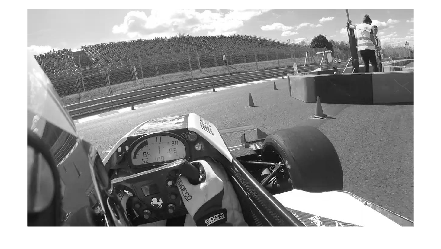

%carico seconda immagine
nextI = 2;
Im2 = readimage(imageFolder, nextI);
Im2 = im2gray(Im2);
imshow(Im2)

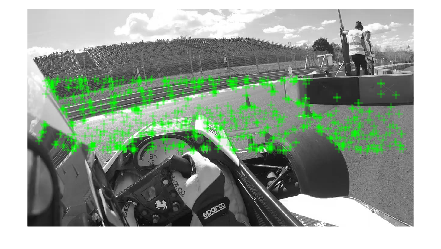

%raccolta delle feature delle due immagini
[feat1, valid1] = dammiFeat(Im1);
[featt2, valid2] = dammiFeat(Im2);
imshow(Im1)
hold on
plot(valid1, 'ShowScale',false)
hold off

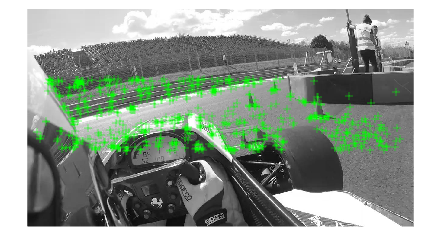

imshow(Im2)
hold on
plot(valid2, 'ShowScale',false)
hold off

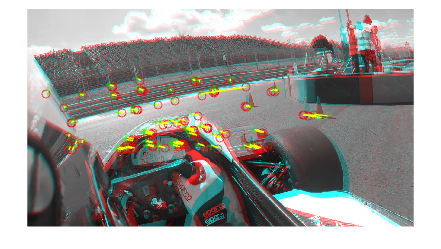

%matching dei punti tra le due immagini
indexPairs = matchFeatures(fit1,fit2);
matchedPoints1 = valid1(indexPairs(:,1),:);
matchedPoints2 = valid2(indexPairs(:,2),:);
figure; 
%il plot è fatto in modo tale che si vede la seconda immagine e in
%trasparenza la prima
showMatchedFeatures(Im1,Im2,matchedPoints1,matchedPoints2);

Funzione per ottenimento punti, si prende un numero aribitrario di punti e da essi si prendono quelli di interesse maggiore

function [feature, validPoint] = dammiFeat(currIm)
%roi è il valore che indica la porzione di immagine in cui cercare riferimenti,
%inutile vedere anche il cielo o la macchina perciò riduco il range
roi = [1 200 1280 300];
orbFeat = detectORBFeatures(currIm, ROI=roi);

n = 1000;
point = selectUniform(orbFeat, n, size(currIm));

[feature, validPoint] = extractFeatures(currIm,point);
end